# Lab 10 - MusicalArduino

------------------------------------------------------------------------------------------------------------------------------------------------------

Created: 2 November 2019

By: Samuel Bechara, Joshua Christopher, and Haile Endeshaw

## Introduction

Buttons are just about everywhere, you probably have about 104 of them on your keyboard right in front of you! Take a look at the cockpit from the space shuttle:

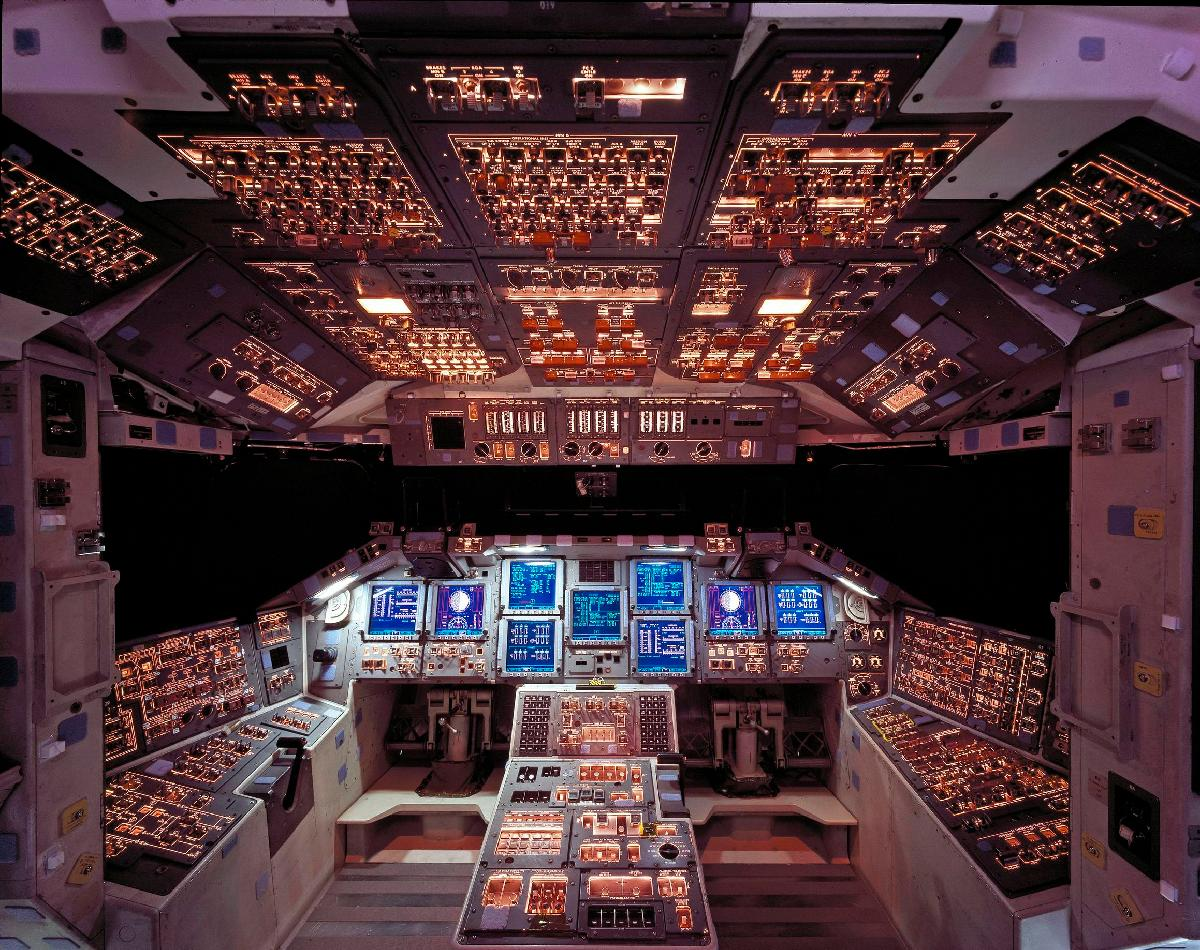

We'd need a bigger Arduino to connect all those buttons, switches, dials, screens, and so on. If you haven't guessed, today we are going to work with the buttons that came with your Arduino kit.

Here is how this lab will be broken up:

- A review of loops and how we have used them in this lab

- The hardware, what goes in to a button?

- The software, how do we do stuff with the buttons?

## Don't repeat yourself... make the Arduino repeat itself!

We are going to write our own loops from scratch for the first time. Loops are one of the most fundamental concepts in programming. Whenever you need to do something again, and again, and again, and again, and again, and .... okay I'll stop. If you are repeating something many times, consider a loop! There are many times during these labs that I had you repeat yourself a lot that would be much easier with a loop. For example in Lab 6 I told you to turn a light on and off 10 times:

clear; close all; clc;
blinky_Arduino = arduino();
ledPin = 'D13';

% Blink built-in LED 10 times
writeDigitalPin(blinky_Arduino,ledPin,0);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,1);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,0);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,1);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,0);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,1);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,0);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,1);

disp('Done!')

That is either a lot of typing or a lot of copy-pasting! Either way since we have 10 repititions that gives us 10 chances to make an error. Lets do the same thing with a lot less typing (and actually turn the light on 10 times) using a **for-end **loop:

clear; close all; clc;
blinky_Arduino = arduino();
ledPin = 'D13';

% Blink built-in LED 10 times
for iteration = 1:10
    writeDigitalPin(blinky_Arduino,ledPin,1);
    fprintf("Times we have turned the light on: %d\n",iteration);
    pause(0.25)
    writeDigitalPin(blinky_Arduino,ledPin,0);
    pause(0.25)
end

I didn't make it exactly the same: I turn the light on at the start of each loop and turned it off at the end of each loop. Also right after turning on the light I print to the Command Window how many times we have turned on the light using the variables `iteration`. Go ahead and give this loop a try with your Arduino!

### While we are on the topic of loops

Another loop we have made a lot of use of in these labs is the **while-end **loop. For example, in Lab 9 we used a while-end loop to check the distance of an object:

% Note: must do new arduinosetup and make sure ultrasonic is selected
clear;close all;clc;

% Setup the pins
TRIG_PIN = 'D8';
ECHO_PIN = 'D7';
% Setup arduino object
distance_Arduino = arduino('/dev/ttyUSB0','Uno','libraries','ultrasonic');
% Set up the ultrasonic
ultraSensor = ultrasonic(distance_Arduino,TRIG_PIN,ECHO_PIN);

% This while loop will run forever, so we will stick our distance reading,
% LED lighting, and noise making inside of here
while(1)
    % Read the distance from the ultrasonic sensor and play sounds or turn
    % on LEDs
    distance = readDistance(ultraSensor);
    
    % Use a pause so we aren't taking a million distance readings per
    % second
    pause(0.5);
end

Your textbook calls this a $\infty$loop, or an infinite loop, because it will run forever (or until you push the pause and stop buttons in Matlab). We used this kind of loop because we wanted to continuously take distance readings. We can also use **while-end** loops when we don't know how long we want to run a loop for. For example, maybe we want to take distance readings until the distance reads zero.

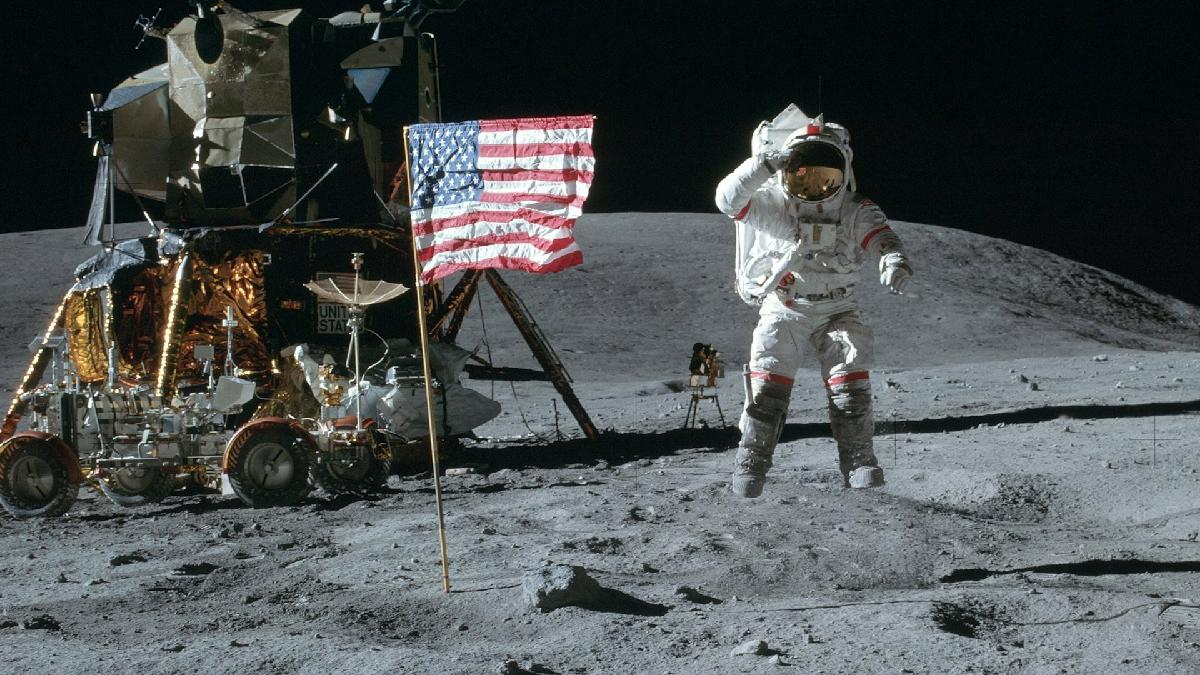

There isn't much use in reading the distance to the surface once you have already landed! But you want to run that while-end loop until something happens (or really "while we are not on the surface"). In that case we write our end-while loops like this:

clear; close all; clc;
distance_Arduino = arduino();

% Set up the pins
TRIG_PIN = 'D8';
ECHO_PIN = 'D7';
% Setup arduino object
distance_Arduino = arduino('/dev/ttyUSB0','Uno','libraries','ultrasonic');
% Set up the arduino for distance
ultraSensor = ultrasonic(distance_Arduino,TRIG_PIN,ECHO_PIN);
distance = readDistance(ultraSensor);

while (distance > 0)
    distance = readDistance(ultraSensor);
    fprintf("We are %f meters from the surface of the moon!", distance);
end

disp("Hello moon!");

After distance is no longer greater than zero, the while-end loop will exit and we can have the Arduino do other things, like saying hello to the moon!

## Hardware: This should really push your buttons

Quick: whats the difference between a button and a switch? 

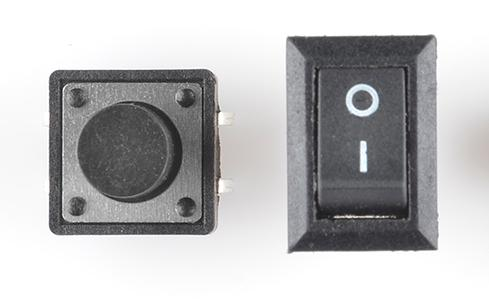

They both do the same thing: they complete an electrical circuit when activated (also called "closing" the circuit). The only difference is that a button typically has a spring in it that re-opens the circuit after you take your finger off the button. A switch will keep the circuit closed until you move it to the off position. In our kits we only have buttons that are more colorful than shown in the picture above. The buttons only fit one way on the breadboard:

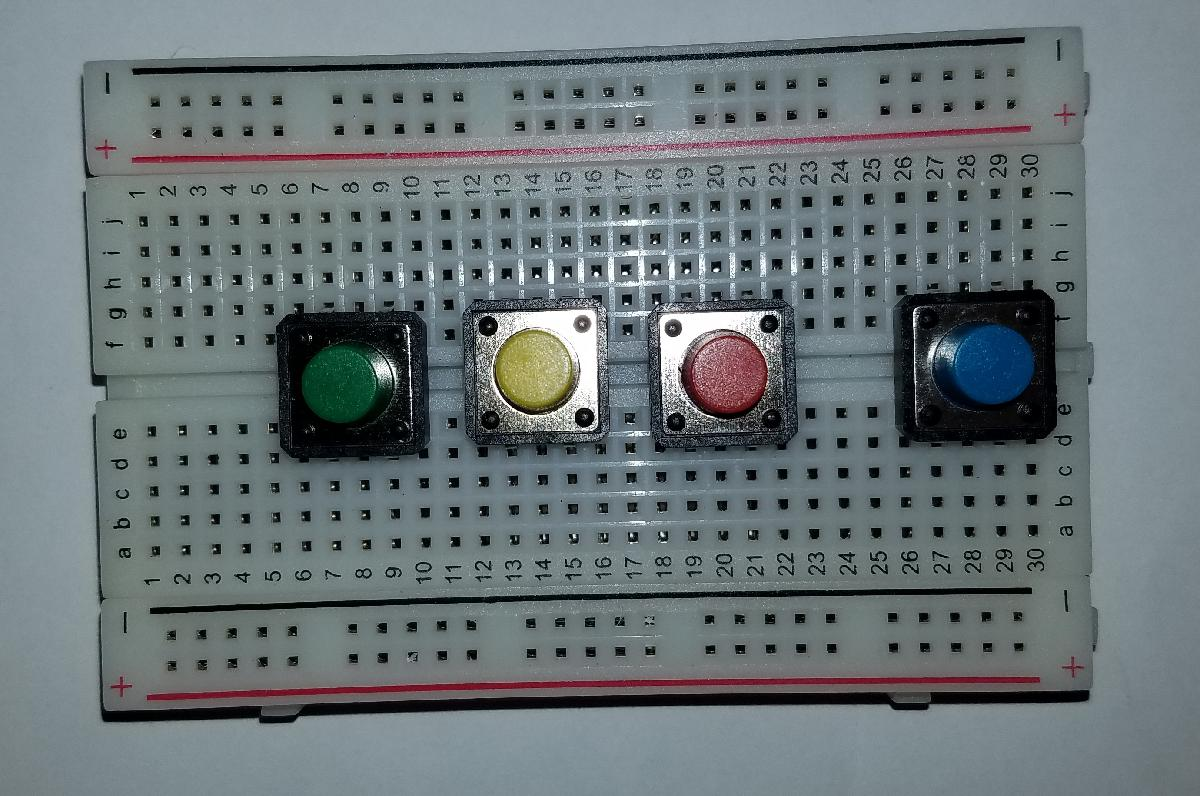

They have to go over that recess in the middle of your breadboard. When you plug the button into your breadboard, its like putting a jumper wire across that recess so that all of the sockets in that row are now electrically connected together. In my picture above, the blue button has its pins in rows 27 and 29. That means that all of row 27 is connected, and all of row 29 is connected. When we push the button down, the button connects row 27 to row 29! Whew, thats a lot of words, lets look at some pictures:

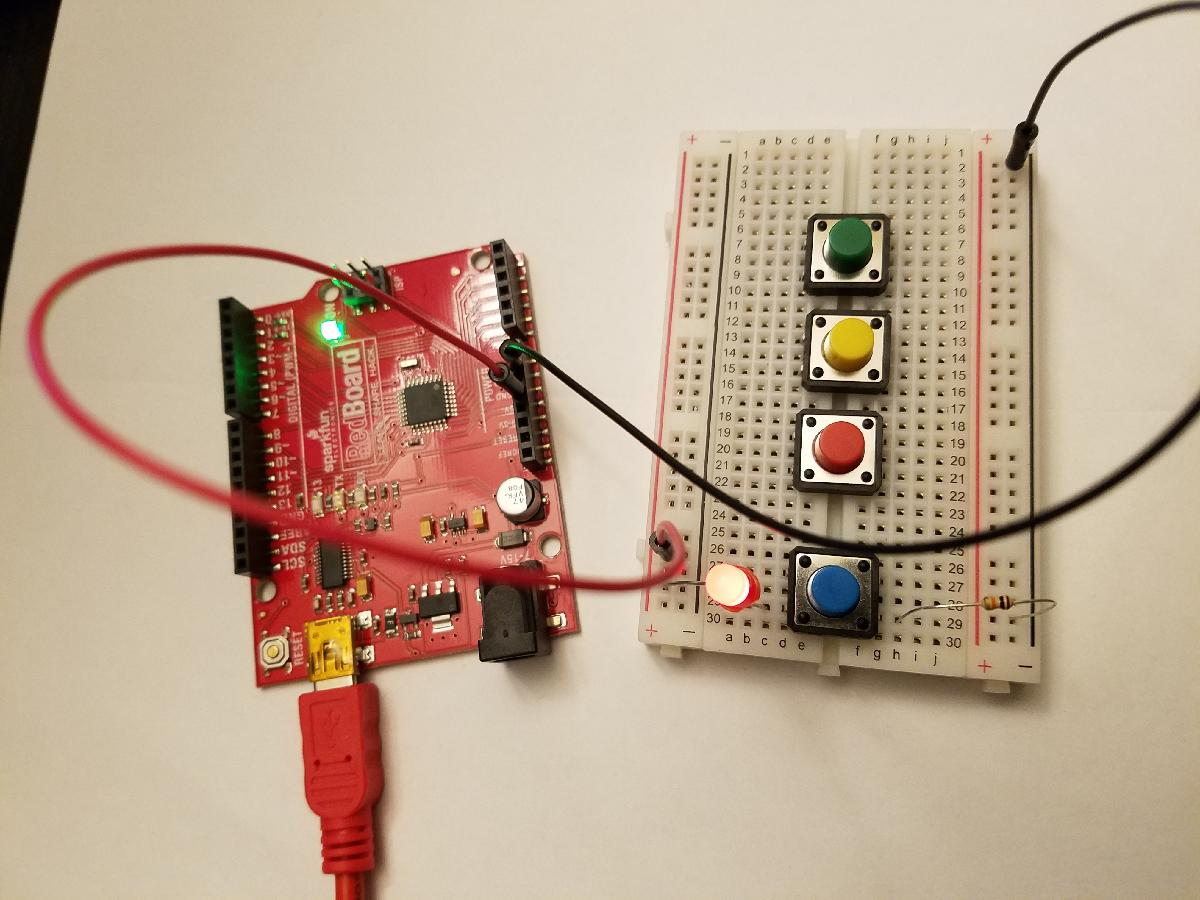

Here I have an LED on left left side of row 29 and a resistor going to ground on the right side of row 29. Even without pushing the button, the circuit is completed and LED is lit.

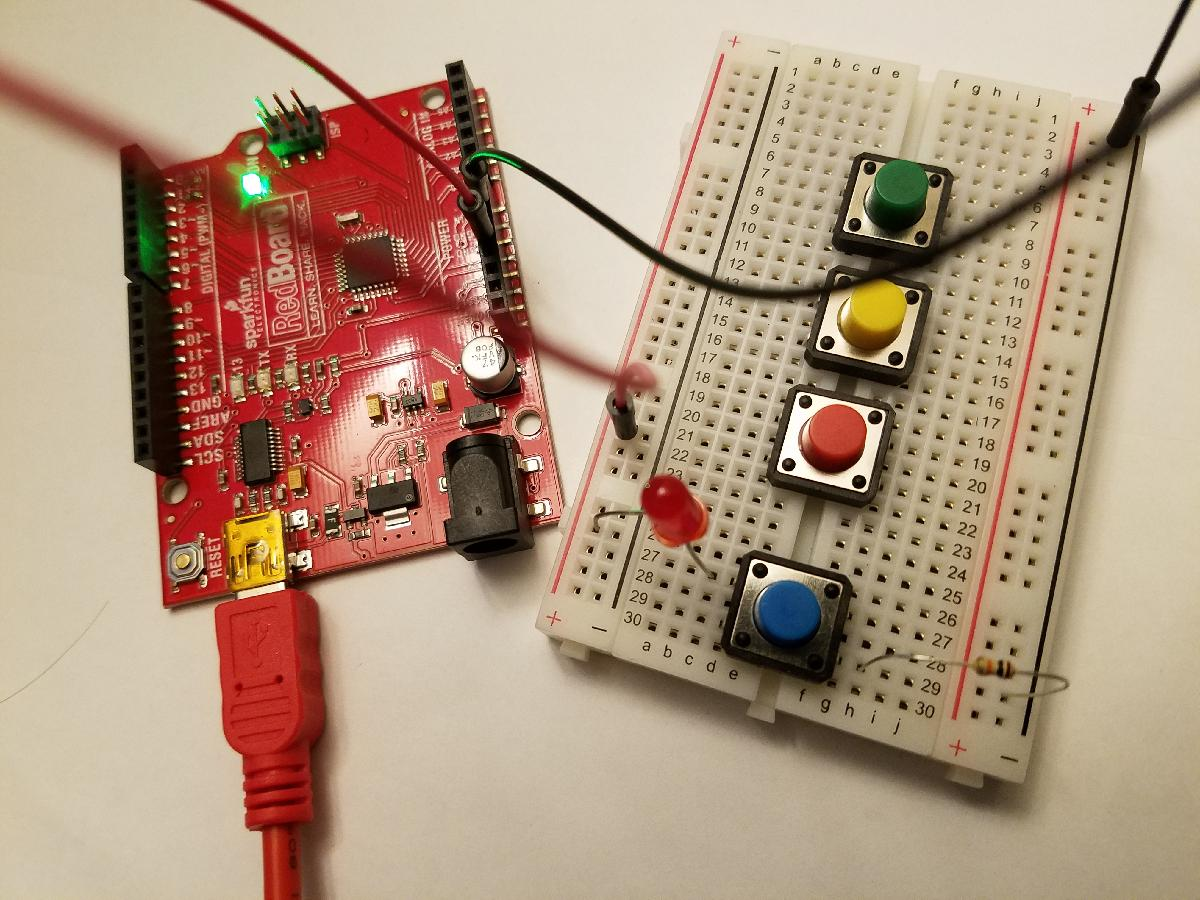

I moved the LED to row 27 and kept the resistor to ground on row 29. When I'm not pushing the button, the circuit is open and the LED is not lit. However, when I push the button:

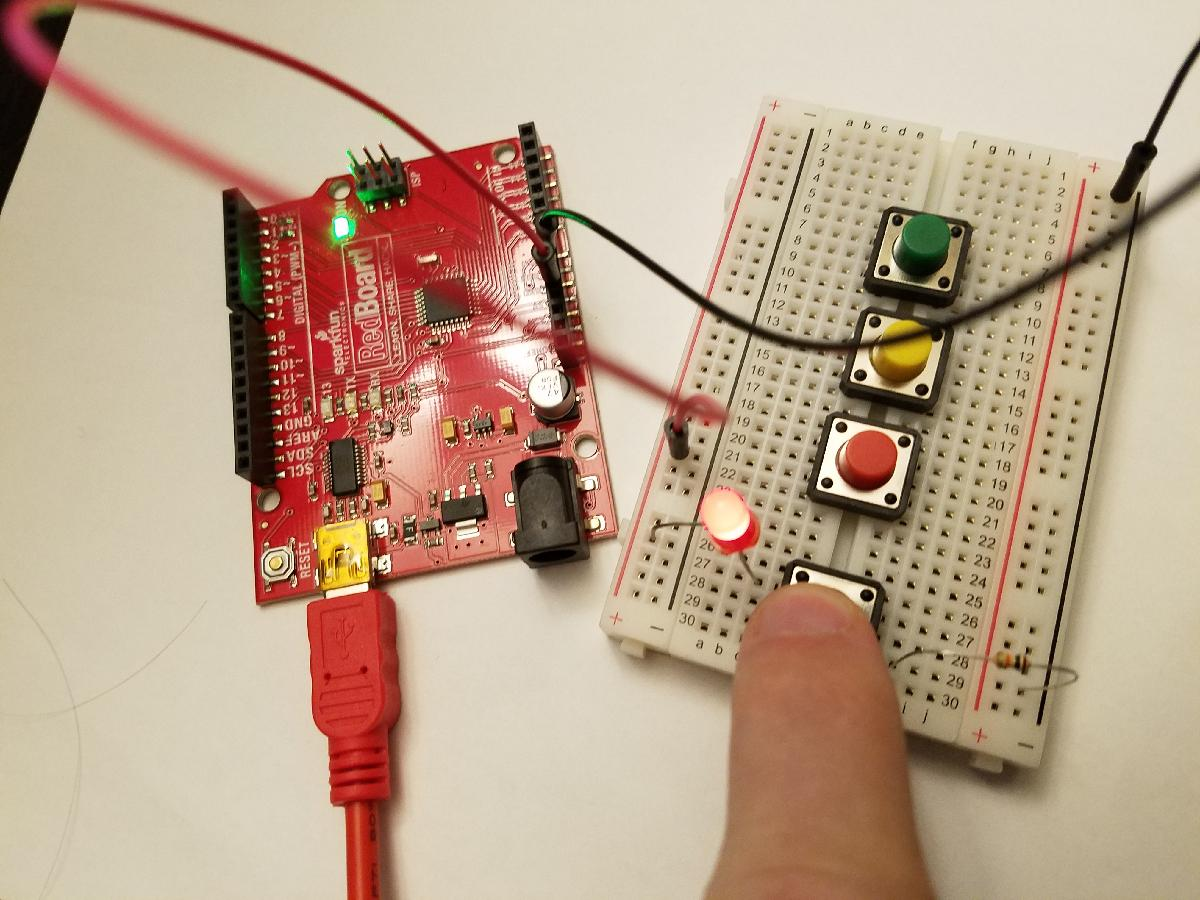

Rows 27 and 29 are electrically connected and the LED turns on!

Lets hook up 3 buttons and the speaker as shown:

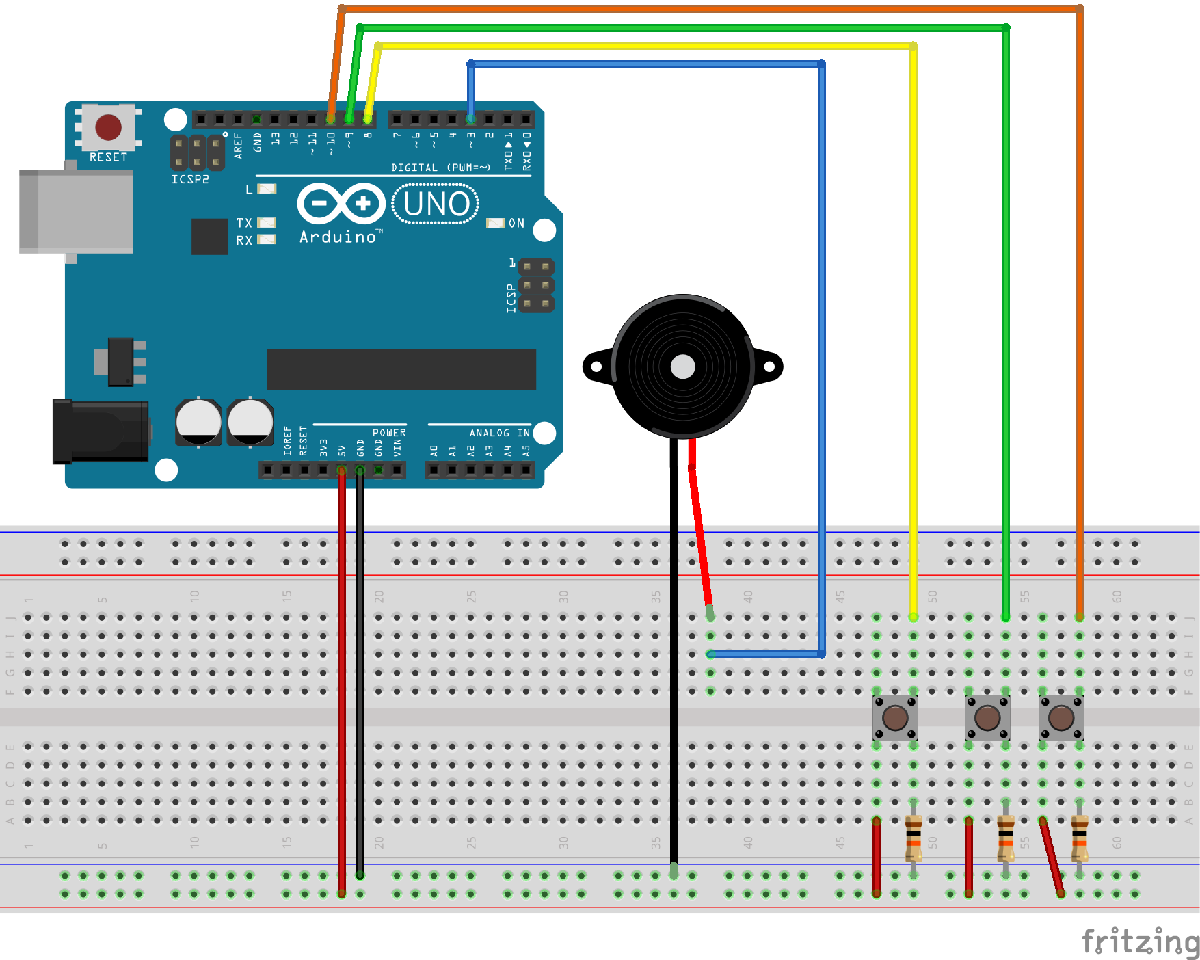

What happens when you push the button in this circuit?

## The Software: At the push of a button

You noticed that the button connects to a digital pin. Thats different than usual: typically we use the digital pins to send a voltage signal out to a LED or a speaker. Now we are going to read a voltage in! We use that with the Matlab function:

clear;
button_arduino = arduino();
button_pin = 'D8';
button_state = readDigitalPin(button_arduino, button_pin);

The functinon `readDigitalPin` has two arguments:

- The arduino object.

- The pin we connected the arduino to.

Go ahead and type `help readDigitalPin` into the Command Window to learn more about it. You see that the function has an output: either a zero or a one. That tells us that the pin is either receiving volage or it is not. So when we push the button we complete a circuit from the positive voltage source to the pin.

Read last week's lab for a review on how to use the speaker.

### Using loops

Like usual, we will need to use an infinite loop to constantly read voltages from the digital pin. Create a Matlab script and write the code for connecting the Arduino and put in an infinite loop like we have done for the past several weeks (we won't need the ultrasonic this week, so you can use the simpler `button_arduino = arduino()` command (and add the port and board name if necessary, like on a Macbook).

Last week the lab talked about **nested if statements**. You can do the same thing with loops, called **nested loops**:

for outer_loop=1:5
    for inner_loop=1:10
        fprintf("Outer loop number: %d and Inner loop number: %d", outer_loop, inner_loop);
    end
end

Think: how many lines will that print to the Command Window? What will the values of `outer_loop` and `inner_loop` be at each loop? **After you think you have figured it out, run it and see if you were right.**

Lets use nested loops now. Inside that infinite while loop we read the diigtal pin and, if the button is pressed, start a new while loop that will play a tone until the button is released. It should look something like this:

button_state = readDigitalPin(button_arduino, button_pin);
if button_state == 1
    while(button_state == 1)
        playTone(button_arduino, SPEAK_PIN, 440, 0.1);
        button_state = readDigitalPin(button_arduino, button_pin);
    end
end

You can use last week's lab to review how to use the `playTone` function.

## The Deliverable

Connect the three buttons and speaker as shown in the figure above. Also connect three LEDs to your Arduino that are the same colors as your buttons. So if you chose red, yellow, and green buttons then connect red, yellow and green LEDs. Then, write a code that does the following:

- When a button is pushed, (a) play a noise from the speaker (b) flash the LED 5 times at a frequency of 4 flashes per second, and (c) after the 5 flashes, keep the LED lit until the button is released. 

- The noise should keep sounding and the LED should stay lit until the button is released.

- This should work for all three buttons.

- The color of button pushed should correspond to the color of LED that lights up.

- Each button should make a different sound. So if you used a frequency of 440 for the green button, use a different frequency for the red and yellow buttons.

Create a flow chart that shows how your circuit works. Turn in the flow chart on Canvas. Bring your completed circuit to next week's lab to demonstrate for your LA that your project meets the requirements above.

Remember that you can copy some of the code from last week's project. From last week, you should already have an infinite loop and some code to have the speaker make a noise and turn on lights. There is no point in re-writing all that from scratch!